# Apply trained model on EEG signals

## UC San Diego Resting State EEG Data from Patients with Parkinson's Disease

fs = 512;
% Downsample by a factor dsFactor
dsFactor = 4;

% read lables
ds = load('raw_labled.mat', 'ls');
ds = ds.ls.Labels;
predLables = ds.detect_blinks;

currentDir = dir;
currentDir(1:2) = [];
for i = 1:numel(currentDir)
    if strcmp(currentDir(i).name,'RawData')
        pathToEEG = fullfile(currentDir(i).folder,currentDir(i).name);
        break
    end
end
eegFiles = dir(pathToEEG);
eegFiles(1:2) = [];
Ds = {};
rawDs = {};
frontElectrodesLabels = ["Fp1", "Fp2", "Fz"]; % , "AF3", "AF4", "F7", "F8"
categroies = {'blink', 'n/a', 'muscle-artifact'};
for k = 1:31
    tokens = strsplit(ds.Row{k}, '\');
    fileName = tokens{end};
    eegTable = readtable([pathToEEG,'\',eegFiles(k).name]);
    filteredSignals = passbandBlinks(eegTable(:, contains(eegTable.Properties.VariableNames, frontElectrodesLabels)), fs);
    DsRaw{k} =eegTable(:, contains(eegTable.Properties.VariableNames, frontElectrodesLabels));
    rawFilteredSignals = passbandBlinks(DsRaw{k}, fs);
    rawFilteredSignals = array2table(filteredSignals.Variables,  'VariableNames', filteredSignals.Properties.VariableNames);
    filteredSignals = array2table(resample(filteredSignals.Variables, 1, dsFactor),  'VariableNames', filteredSignals.Properties.VariableNames);
    roi = ds(k,:).detect_blinks{1};
    rawDs{k} = getmask({rawFilteredSignals, roi});

    roi(:, 1).Variables = ceil(roi(:, 1).Variables/dsFactor);
    masked = getmask({filteredSignals, roi});
    rawDs{k}{2} = categorical(rawDs{k}{2},categroies);

    Ds{k} = masked; 
    Ds{k}{2} = categorical(Ds{k}{2},categroies);
end

new data set

Abdu =  readtable("DataSet\Abdu.csv");


fs = 250;

dsFactor = 8;

Ds = {};
rawDs = {};

k=1;

    eegTable = Abdu;
    filteredSignals = passbandBlinks(eegTable(:, 1:3), fs);
    DsRaw{k} =eegTable(:, 1:3);
    rawFilteredSignals = passbandBlinks(DsRaw{k}, fs);
    rawFilteredSignals = array2table(filteredSignals.Variables,  'VariableNames', filteredSignals.Properties.VariableNames);
    filteredSignals = array2table(resample(filteredSignals.Variables, 1, dsFactor),  'VariableNames', filteredSignals.Properties.VariableNames);
    roi = ds(k,:).detect_blinks{1};
    rawDs{k} = getmask({rawFilteredSignals, roi});

    roi(:, 1).Variables = ceil(roi(:, 1).Variables/dsFactor);
    masked = getmask({filteredSignals, roi});
    rawDs{k}{2} = categorical(rawDs{k}{2},categroies);

    Ds{k} = masked; 
    Ds{k}{2} = categorical(Ds{k}{2},categroies);


% 
% for i = 1:numel(Ds)
%     oneSubj = {};
%     shiftSubj = {};
%     for j = 1:slice-1:size(,1)-slice
%         oneSubj{end+1,1} =table2array((j:j+slice-1,:))';        
%     end
% end





slice = 512;
chopedDs = {};
shiftChopedDs={};
for i = 1:numel(Ds)
    oneSubj = {};
    shiftSubj = {};
    for j = 1:slice-1:size(Ds{i}{1},1)-slice
        oneSubj{end+1,1} =table2array(Ds{i}{1}(j:j+slice-2,:))';        
    end
    for j = slice/2:slice-1:size(Ds{i}{1},1)-slice
        shiftSubj{end+1,1} = table2array(Ds{i}{1}(j:j+slice-2,:))';        
    end
    chopedDs{end+1} = {oneSubj};
    shiftChopedDs{end+1} = {shiftSubj};
end

TCNnet = load('Models\trainedModels\LSTMnet.mat').net;

predLocations = {};
predLables = {};
for i = 1:numel(chopedDs)
    X = chopedDs{i}{:};
    sX = shiftChopedDs{i}{:};
    
    YPred = classify(TCNnet,X);
    sYPred = classify(TCNnet,sX);
    
    lable = [];sLable = [];
    blinkLocation = [];
    
    for j = 1:size(YPred,1)
        YPred{j} = YPred{j};%(1:slice);
        addOn = [];
        for d = 1:dsFactor
            addOn = [addOn;YPred{j}];
        end
        lable = [lable,reshape(addOn,[1 (slice-1)*dsFactor])];
    end  
%     for j = 1:size(sYPred,1)
%         sYPred{j} = sYPred{j}(1:slice-1);        
%         sLable = [sLable,reshape([sYPred{j};sYPred{j};sYPred{j};sYPred{j}],[1 (slice-1)*dsFactor])];
%     end
%     if numel(YPred) == numel(sYPred)
%         lable = [lable sLable(end-slice*dsFactor/2+1:end)];
%     end
% 
%     if numel(YPred) == numel(sYPred)
%         lable(lable(slice*dsFactor:end) ~= sLable(1:end-slice*dsFactor+1)) = 'n/a';
%         summaryLable = [lable sLable(end-slice*dsFactor:end)];
%     else 
%         lable(lable(slice*dsFactor:end-slice*dsFactor) ~= sLable(1:end-slice*dsFactor-dsFactor +1)) = 'n/a';
%         summaryLable = [lable ];
% 
%     end
    blinkLocation = blinkLocate(table2array(rawDs{i}{1}),lable);
    predLocations{i} = blinkLocation;
    predLables{i} = lable;
end

% location = load('DataSet\blinkLocations.mat').blinkLocations;
% all = 0;
% find = 0;
% for i = 1:numel(location)
%     all = all + size(location{i}{1},2);
%     find = find + size(intersect(location{i}{1},predLocations{i}),2);
% end
% all,find,find/all

for i=1;
    figure;
    signal = table2array(rawDs{i}{1});%table2array(Ds{i}{1});
    
    
    figure;
    coordinate = signal(predLocations{i},1);
    subplot(2,1,1);
    hold on;
%     M = signalMask(lables{i});
%     plotsigroi(M,rawDs{i}{1}.Fp1);
    plot(rawDs{i}{1}.Var1);
    plot(predLocations{i},coordinate,'r*');
    hold off;
    raw = eegTable(:, 1:3);
    subplot(2,1,2);
    hold on;
    plot(raw.Var1);
    coordinate = raw.Var1(predLocations{i});
    plot(predLocations{i},coordinate,'r*');
    hold off;

%     coordinate = signal(location{i}{1},1);
%     subplot(2,1,2);
%     hold on;
%     M = signalMask(rawDs{i}{2});
%     plotsigroi(M,rawDs{i}{1}.Fp1);
%     plot(location{i}{1},coordinate,'r*');
%     hold off;
end

## EEG IQ Test Experiment (Rafal Paprocki and Artem Lenskiy Dataset)

currentDir = dir("DataSet\ModelApplication\EEG IQ Test Experiment");
currentDir(1:2) = [];
fs = 250;
dsFactor = 2048;
slice = 512;
Ds = {};
rawDs = {};
frontElectrodesLabels = ["Fp1", "Fp2", "Fz"];
for i = 1:numel(currentDir)
    eegTable =  readtable([currentDir(i).folder '\' currentDir(i).name]);
    subj = eegTable(:, ["Var1","Var2","Var5"]);

    filteredSignals = passbandBlinks(subj, fs);
    rawDs{end+1} = filteredSignals;
    filteredSignals = array2table(resample(filteredSignals.Variables, slice, 4*fs),  'VariableNames', filteredSignals.Properties.VariableNames);
   
    Ds{end+1} = filteredSignals;
end

TCN

TCNnet = load('Models\trainedModels\TCNnet.mat').net;

predLocations = {};
predLables = {};
chopedDs = {};
shiftChopedDs={};

tic;
for i = 1:1%numel(Ds)
    oneSubj = {};
    shiftSubj = {};
    for j = 1:slice:size(Ds{i},1)-slice
        oneSubj{end+1,1} = table2array(Ds{i}(j:j+slice-1,:))';        
    end
%     for j = slice/2:slice-1:size(Ds{i},1)-slice
%         shiftSubj{end+1,1} = table2array(Ds{i}(j:j+slice-2,:))';        
%     end
    chopedDs{i} = oneSubj;
    shiftChopedDs{i} = shiftSubj;

    
    X = oneSubj;
    sX = shiftSubj;

    YPred = classify(TCNnet,X);
%         sYPred = classify(TCNnet,sX);
    
    lable = [];sLable = [];
    blinkLocation = [];
    
    for k = 1:size(YPred)
        %YPred{j} = YPred{j};%(1:slice);
%             addOn = [];
%             for d = 1:dsFactor
%                 addOn = [addOn;YPred{k}];
%             end
%             lable = [lable,reshape(addOn,[1 (slice-1)*dsFactor])];
        lable = [lable,YPred{k}];
    end  
    blinkLocation = blinkLocate(table2array(Ds{i}),lable);

    
    predLocations{i} = blinkLocation;
    predLables{i} = lable;
    
end
toc

Elapsed time is 1.088843 seconds.


% TCNresultIQTest = {predLocations,predLables};
% save("Test\Results\TCNresultIQTest.mat","TCNresultIQTest","-mat");

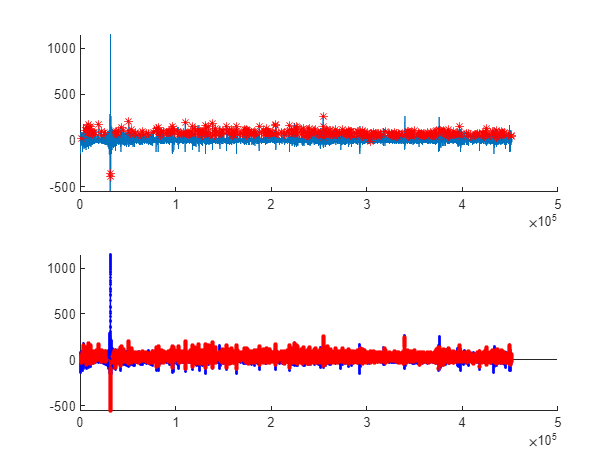

% predLocations,predLables = load("Test\Results\TCNresultIQTest.mat").TCNresultIQTest;
for i=1;
    figure;
    signal = table2array(rawDs{i});
    signal = signal(:,1);
    location = round(predLocations{i}*4*fs/slice);
%     lables = resample(predLables{i},4*fs,slice);
    lables = predLables{i};
    figure;
    coordinate = signal(location);
    subplot(2,1,1);
    hold on;

    plot(signal);
    plot(location,coordinate,'r*');
    hold off;
    
%     subplot(3,1,2);
%     hold on;
%     plot(signal(:,1));
%     plot(predLocations{i},coordinate,'r*');
%     hold off;

    subplot(2,1,2);
    hold on;
    plot(signal);
    %coordinate = Ds{i}.Var1(predLocations{i});

    stem(round(find(lables == "muscle-artifact")*fs*4/slice),signal(round(find(lables == "muscle-artifact")*fs*4/slice)),LineWidth=1,Color='b',MarkerSize=1);
    stem(round(find(lables == "n/a")*fs*4/slice),signal(round(find(lables == "n/a")*fs*4/slice)),LineWidth=1,Color='b',MarkerSize=1);
    stem(round(find(lables == "blink")*fs*4/slice),signal(round(find(lables == "blink")*fs*4/slice)),LineWidth=1,Color='r',MarkerSize=2);
    hold off;

end

LSTM

LSTMnet = load('Models\trainedModels\LSTMnet.mat').net;
slice = 512;
predLocations = {};
predLables = {};
% chopedDs = {};
% shiftChopedDs={};

for i = 1:1%numel(Ds)

% 
%     oneSubj = {};
%     shiftSubj = {};
%     for j = 1:slice-1:size(Ds{i},1)-slice
%         oneSubj{end+1,1} =table2array(Ds{i}(j:j+slice-2,:))';        
%     end
%     for j = slice/2:slice-1:size(Ds{i},1)-slice
%         shiftSubj{end+1,1} = table2array(Ds{i}(j:j+slice-2,:))';        
%     end
%     chopedDs{end+1} = oneSubj;
%     shiftChopedDs{end+1} = shiftSubj;

    

    for j = 1:numel(chopedDs{end})
        X = chopedDs{end};
        sX = shiftChopedDs{end};
        
        YPred = classify(LSTMnet,X);
        sYPred = classify(LSTMnet,sX);
        
        lable = [];sLable = [];
        blinkLocation = [];
        
        for k = 1:size(YPred)
            %YPred{j} = YPred{j};%(1:slice);
            addOn = [];
            for d = 1:dsFactor
                addOn = [addOn;YPred{k}];
            end
            lable = [lable,reshape(addOn,[1 (slice-1)*dsFactor])];
        end  
        blinkLocation = blinkLocate(table2array(rawDs{i}),lable);
    
    end
    predLocations{i} = blinkLocation;
    predLables{i} = lable;
    
end

Error using DAGNetwork/classify
Invalid prediction data. Predictors must be a N-by-1 cell array of sequences, where N is the number of sequences.  All sequences must have the same
feature dimension and at least one time step.

LSTMresultIQTest = {predLocations,predLables};
save("Test\Results\LSTMresultIQTest.mat","LSTMresultIQTest","-mat");

predLocations, predLables = load("Test\Results\LSTMresultIQTest.mat").LSTMresultIQTest;
for i=7;
    figure;
    signal = table2array(rawDs{i});
    
    figure;
    coordinate = signal(predLocations{i},1);
    subplot(2,1,1);
    hold on;

    plot(rawDs{i}.Var1);
    plot(predLocations{i},coordinate,'r*');
    hold off;
    
%     subplot(3,1,2);
%     hold on;
%     plot(signal(:,1));
%     plot(predLocations{i},coordinate,'r*');
%     hold off;

    subplot(2,1,2);
    hold on;
    plot(rawDs{i}.Var1);
    %coordinate = Ds{i}.Var1(predLocations{i});

    stem(find(predLables{i} == "muscle-artifact"),rawDs{i}.Var1(predLables{i} == "muscle-artifact"),LineWidth=1,Color='b',MarkerSize=1);
    stem(find(predLables{i} == "n/a"),rawDs{i}.Var1(predLables{i} == "n/a"),LineWidth=1,Color='b',MarkerSize=1);
    stem(find(predLables{i} == "blink"),rawDs{i}.Var1(predLables{i} == "blink"),LineWidth=1,Color='r',MarkerSize=2);
    hold off;

end


%WT



